% scope_radar_detection.mlx

clear;

% This calls helper functions and outputs a determination of whether a
% human, given the data collected, has been found
% More attention is drawn towards mitigating false alarms

num_segments = 2;
freq_cutoff_ratio = 0.4;
snr = 5;
decomp_level = 1;
num_pt_fit = 3;
trigger_slope = 0.5;

num_trials = 10;

% calculate detections (for the cases that require detections)
detections = zeros(1,7*2*2);
xlabels = {};
index = 0;
for distance = 1:7
    for motion = 2:3
        for obstacle = 1:2
            xlabels(end+1) = {sprintf("d%im%io%i",distance,motion,obstacle)};
            index = index + 1;
            for trial = 1:num_trials
                filename = sprintf("test_%i_%i_%i_%i.mat",distance,motion,obstacle,trial);
                filename = fullfile(pwd,'/testing/matfiles',filename);
                % Calculate arrival times
                [~,toa_arr] = toa_phase_calculate(filename,num_segments,freq_cutoff_ratio,snr,decomp_level,trigger_slope,num_pt_fit);
                % If more than one element in the array, consider a detection
                detections(1,index) = detections(1,index) + double(~isempty(toa_arr));
            end
        end
    end
end

overall_detection_rate = sum(detections) / (index*num_trials)

overall_detection_rate = 0.7071

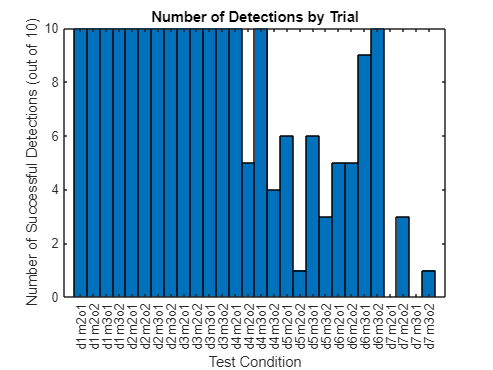


bar_width = 1.0;
figure;
% Create bar graph
bar(1:numel(detections),detections,bar_width)
% Set x-axis labels
xticks(1:numel(detections))
xticklabels(xlabels)
title("Number of Detections by Trial")
ylabel("Number of Successful Detections (out of 10)")
xlabel("Test Condition")


% false_alarms = zeros(1,7*1*2);
% index = 0;
% xlabels = {};
% % calculate false alarms
% for distance = 1:7
%     for motion = 1:1
%         for obstacle = 1:2
%             xlabels(end+1) = {sprintf("d%im%io%i",distance,motion,obstacle)};
%             index = index + 1;
%             for trial = 1:num_trials
%                 filename = sprintf("test_%i_%i_%i_%i.mat",distance,motion,obstacle,trial);
%                 filename = fullfile(pwd,'/testing/matfiles',filename);
%                 % Calculate arrival times
%                 toa_arr = toa_phase_calculate(filename,num_segments,freq_cutoff_ratio,snr,decomp_level,trigger_slope,num_pt_fit);
%                 % If more than one element in the array, consider a false alarm
%                 false_alarms(1,index) = false_alarms(1,index) + double(~isempty(toa_arr));
%             end
%         end
%     end
% end
% 
% overall_false_alarm_rate = sum(false_alarms) / (index * num_trials)
% 
% % Create bar graph
% figure;
% bar(1:numel(false_alarms),false_alarms,bar_width)
% % Set x-axis labels
% xticks(1:numel(false_alarms))
% xticklabels(xlabels)
% title("Number of False Alarms by Test Condition")
% ylabel("Number of False Alarms (out of 10 trials)")
% xlabel("Test Condition")

% bar_width = 1.0;
% SNR = zeros(1,7*2*1);
% snr_avg_array = zeros(1,7*2*1);
% index = 0;
% xlabels = {};
% % calculate false alarms
% for distance = 1:7
%     for motion = 2:3
%         for obstacle = 2:2
%             xlabels(end+1) = {sprintf("d%im%io%i",distance,motion,obstacle)};
%             index = index + 1;
%             for trial = 1:num_trials
%                 filename = sprintf("test_%i_%i_%i_%i.mat",distance,motion,obstacle,trial);
%                 filename = fullfile(pwd,'/testing/matfiles',filename);
%                 % Calculate arrival times
%                 [snr,toa_arr] = toa_phase_calculate(filename,num_segments,freq_cutoff_ratio,snr,decomp_level,trigger_slope,num_pt_fit);
%                 % If more than one element in the array, consider a false alarm
%                 snr_avg_array(1,index) = snr;
%             end
%         end
%     end
% end
% 
% overall_snr = sum(snr_avg_array) / (index * num_trials);
% 
% % Create bar graph
% figure;
% bar(1:numel(snr_avg_array),snr_avg_array,bar_width)
% % Set x-axis labels
% xticks(1:numel(snr_avg_array))
% xticklabels(xlabels)
% title("SNR by Test Condition, At Filter Freq Proportion Cutoff = 0.4")
% ylabel("SNR")
% xlabel("Test Condition")
